subs = {'01' '02' '03'}

subs = 1×3 cell array
    {'01'}    {'02'}    {'03'}


for ii = 1:numel(subs)
    sub = subs{ii}

datadir = 'C:\Users\bgrau\GitHub\ieeg_affect\EEE\subjects';
sesdir = fullfile(datadir, ['sub-', sub], 'ses-01' );


EEE Subject Total Effect Readout:

cd(sesdir)
% clear all
load('stim_table_full.mat')
stim_table = movevars(stim_table, 'val_rating', 'After', 'cue_observed_mean');
% stim_table = stim_table(:, [1:4 6:9 11 12 14 15 31 33]);

cs = find(contains(stim_table.Properties.VariableNames, 'mean'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'SD'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'std'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'difference'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'deviation'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'rating'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;

for i = 1:64
    stim_table.sub{i} = str2double(sub);
end

stim_table = sortrows(stim_table,"Pair","ascend");


sub = '01'

sub = '02'

sub = '03'

cuehl = stim_table.highcue_indx;
cuemean = stim_table.cue_observed_mean;
pair = stim_table.Pair;
rating = stim_table.val_rating;
stimmean = stim_table.Valence_mean;



wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = stim_table(wh_high, :);
lo_table = stim_table(wh_low, :);


pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_val = hi_table.val_rating;
pair_table.lo_val = lo_table.val_rating;
pair_table.hi_exp = hi_table.exp_rating;
pair_table.lo_exp = lo_table.exp_rating;
pair_table.exp_mean = (pair_table.hi_exp + pair_table.lo_exp) /2;
pair_table.rating_mean = (hi_table.val_rating + lo_table.val_rating)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.val_rating - lo_table.val_rating;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
d = pair_table.rating_diff;

% Two-tailed
[hyp, pval, ci, stat] = ttest(hi_table.val_rating, lo_table.val_rating, 'Tail', 'right');
% [hyp, pval, ci, stat] = ttest(stim_table.val_rating - stim_table.Valence_mean);

fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));

High vs. low cue effect: M = 6.66, SE = 2.39, t( 31) = 2.78, p = 0.004580


High vs. low cue effect: M = 2.86, SE = 2.62, t( 31) = 1.09, p = 0.141811


High vs. low cue effect: M = 6.56, SE = 3.68, t( 31) = 1.78, p = 0.042206


Cue Effect (ordered by pair number)


cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Normalized Valence Rating by Image Pair')
% axis([0 33 -40 40])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;


cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Raw Valence Rating by Image Pair')
axis([0 33 0 125])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

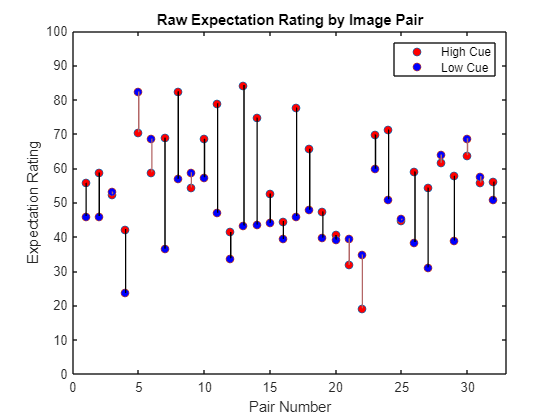



y = [pair_table.hi_exp-pair_table.exp_mean pair_table.lo_exp-pair_table.exp_mean];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating');
title('Normalized Expectation Rating by Image Pair')
axis([0 33 -40 40])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

y = [pair_table.hi_exp pair_table.lo_exp];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;


lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Expectation Rating');
title('Raw Expectation Rating by Image Pair')
axis([0 33 0 100])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

hold off;

figure; hold on;
g = gramm('x', pair_table.pair_number, 'y', d);
    % g.stat_violin('fill', 'transparent');
    g.geom_point();
    g.set_names('x', 'High vs. Low Cue', 'y', 'Valence Rating');
    g.draw();


I think that there's something interesting happening when individuals have strong pre-existing preferences for an image. I'll try to quantify that by looking at ratings that are more than 2 SD away from the normative mean. 

hi_sd = pair_table.stim_mean + (2*pair_table.stim_sd);
lo_sd = pair_table.stim_mean - (2*pair_table.stim_sd);
hold on;
highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');

sd_up = plot(hi_sd, 'k-');
sd_down = plot(lo_sd, 'k-');

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
hold off;
axis([0 33 -20 139])
legend([highdots lowdots meandots sd_up], {'High Cue', 'Low Cue', 'Normative Rating', '2*SD of Normative'})


Cue Effect (ordered from largest to smallest)

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);


xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating (unp to pleasant)')
hold off;

axis([0 33 0 135])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val-pair_table.rating_mean pair_table.lo_val-pair_table.rating_mean];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

title('Cue Type Positively Correlates with Valence Rating')
xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating Within Picture Pairs')
hold off;

axis([0 33 -50 70])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Control of Cue Effect 

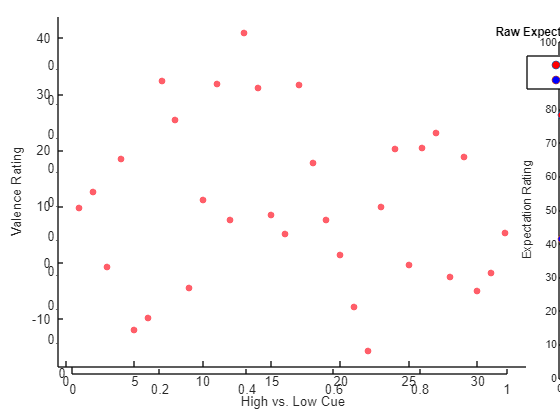

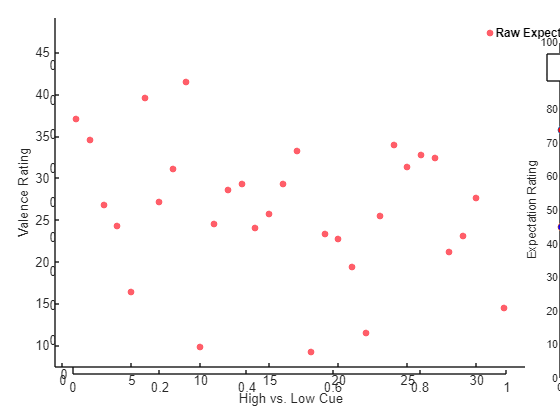

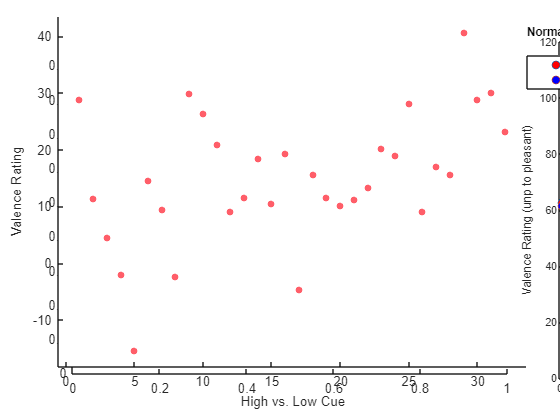



y = [hi_table.Valence_mean lo_table.Valence_mean];  % ratings, [high low]
x = [hi_table.Pair lo_table.Pair];  % pairs, [high low]

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;


lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); hold off;

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
title('Normative Valence Ratings')
hold off;
axis([0 33 0 120])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Averge Effect: 

% % Extract and compute normative H-L cue picture rating differences
normative_diff = pair_table.stim_diff;
% 
% Perform the regression model
X = [ones(size(normative_diff, 1), 1), normative_diff];
y = pair_table.rating_diff;
coeffs = regress(y, X);

% Extract the intercept term (effect of interest)
intercept = coeffs(1);

% Display the results
fprintf('Intercept (patient average H-L cue effect): %.4f\n', intercept);

Intercept (patient average H-L cue effect): 6.6746


Intercept (patient average H-L cue effect): 2.5777


Intercept (patient average H-L cue effect): 6.4244


Grand Average

if exist('full_stim') == 0
    full_stim = stim_table;
    full_hi = hi_table;
    full_lo = lo_table;
else 
    full_stim = [full_stim; stim_table];
    full_hi = [full_hi; hi_table];
    full_lo = [full_lo; lo_table];
end

end

[hyp, pval, ci, stat] = ttest(full_hi.val_rating, full_lo.val_rating, 'Tail', 'right')

hyp = 1

pval = 0.0011

ci =     2.5419
       Inf


stat = struct with fields:
    tstat: 3.1595
       df: 95
       sd: 16.6206



data = table();
data.subj = categorical(string(full_stim.sub));
data.Pair = categorical(full_stim.Pair);
data.Image = categorical(full_stim.Image);
data.Theme = full_stim.Theme;
% data.val_type = categorical(full_stim.val_type);
% data.Half = categorical(full_stim.Half);
data.img_rate = full_stim.val_rating;
data.exp_rate = full_stim.exp_rating;
data.Valence_mean = full_stim.Valence_mean;
data.cue_mean = full_stim.cue_observed_mean;
% data.group = categorical(full_stim.group);
data.highcue_indx = categorical(full_stim.highcue_indx); 
data.norm_val = full_stim.Valence_mean - mean(full_stim.Valence_mean);
data.norm_cue = full_stim.cue_observed_mean - mean(full_stim.cue_observed_mean,  "omitmissing");

comp = fitlme(data, 'img_rate ~ 1 + highcue_indx + Valence_mean + (highcue_indx + Valence_mean | subj)', 'FitMethod', 'REML') 

comp = Linear mixed-effects model fit by REML

Model information:
    Number of observations             192
    Fixed effects coefficients           3
    Random effects coefficients          9
    Covariance parameters                7

Formula:
    img_rate ~ 1 + Valence_mean + highcue_indx + (1 + Valence_mean + highcue_indx | subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1645.7    1678.1    -812.84          1625.7  

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat      DF     pValue        Lower      Upper 
    {'(Intercept)'   }        -10.207      13.818    -0.7387    189       0.46101    -37.464     17.05
    {'Valence_mean'  }         1.1225     0.20721     5.4172    189    1.8272e-07    0.71377    1.5313
    {'highcue_indx_1'}         5.4319      2.4975     2.1749    189       0.03088    0.50524    10.358

<s

anova(comp, 'dfmethod', 'satterthwaite') 

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                    FStat      DF1    DF2       pValue  
    {'(Intercept)' }        0.54568    1      2.0007     0.53699
    {'Valence_mean'}         29.346    1      2.0002    0.032421
    {'highcue_indx'}         4.7302    1      12.957    0.048755
